## 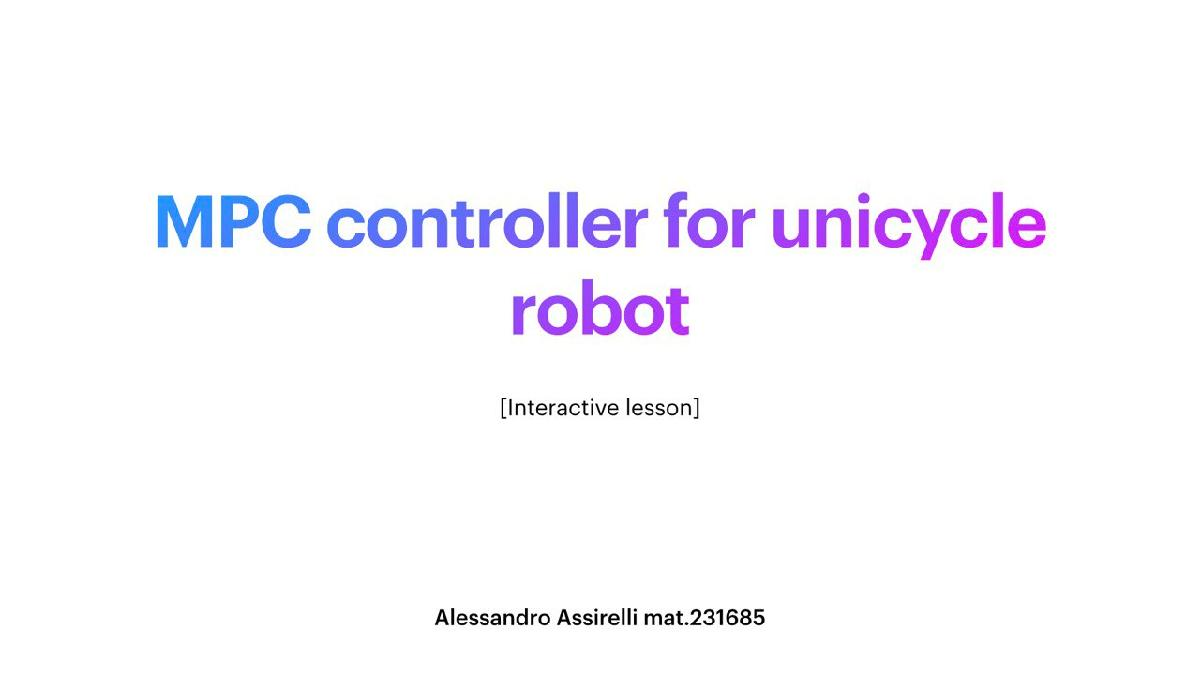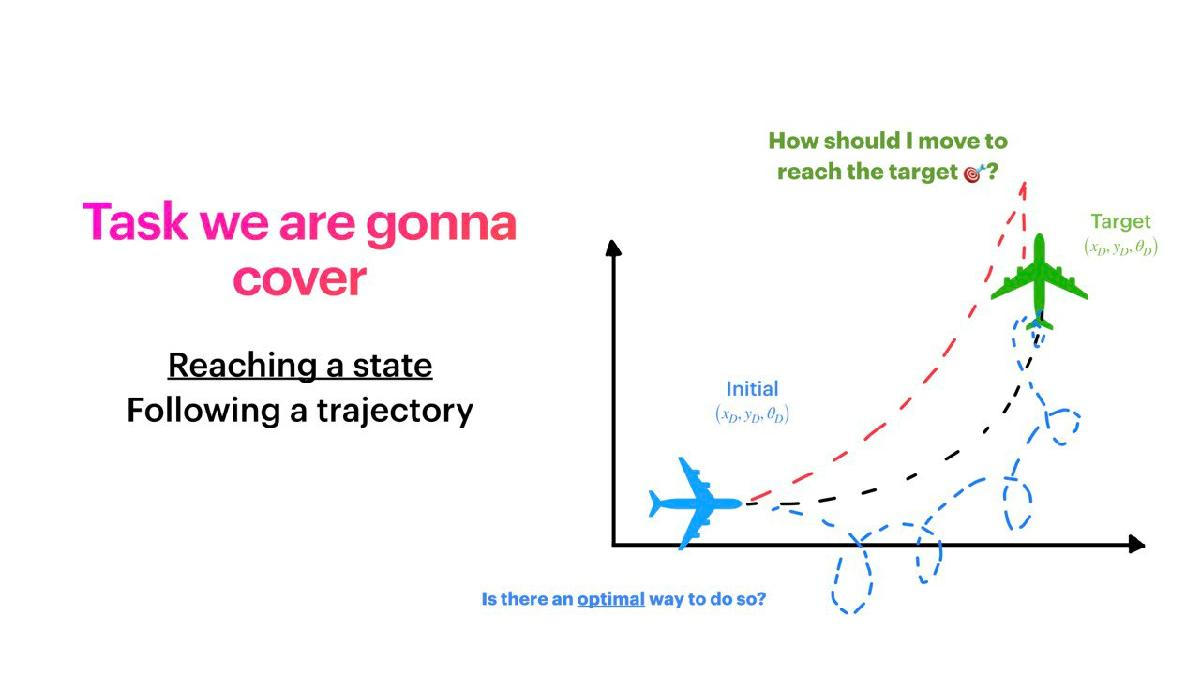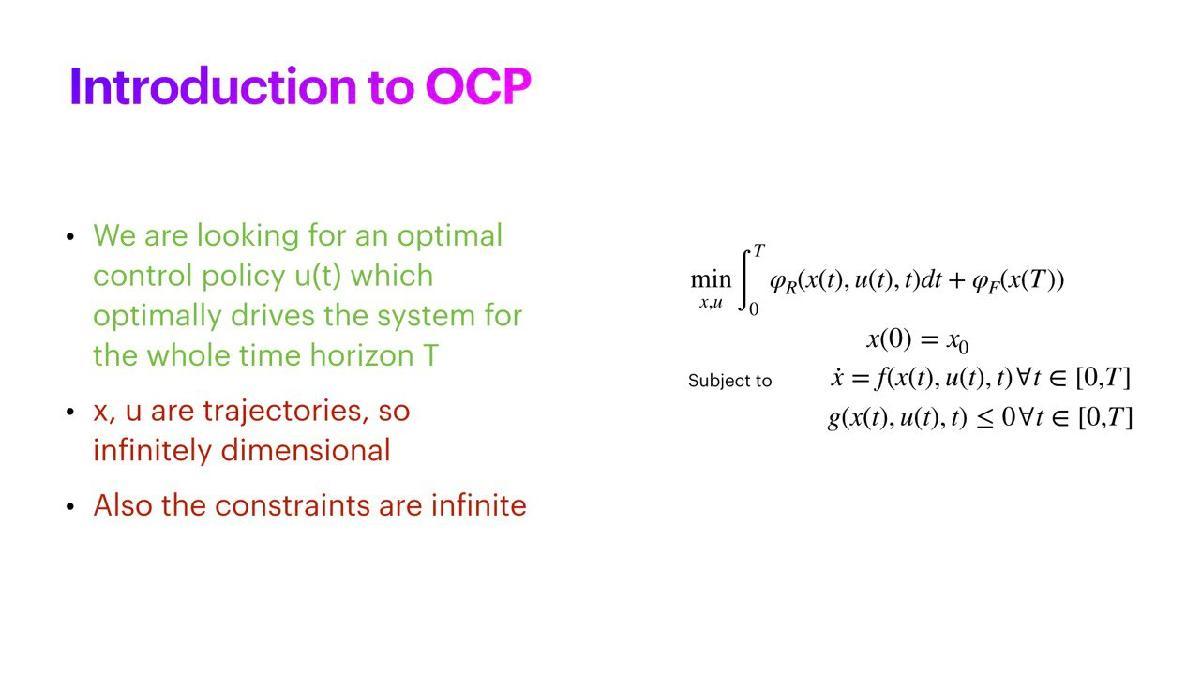

- In order to run this script you must ensure to have the "functions" folder in your working directory

## MPC Control of a differential drive unicycle

This is a live script which implements a MPC controller for a differential drive unicycle. There are various topic covered here:

- Implementation of multiple shooting to solve an optimal control problem

- Solve a trajectory optimization and apply the optimal actions in open loop

- Close the loop by implementing a MPC algorithm for the point to point motion problem

- Implement a trajectory tracking MPC

close all;
clear;
clc

addpath(genpath(pwd))
import casadi.*

dt = 0.01;
T = 3; % Time horizon of the optimal control problem
N = round(T/dt,0); % Number of timesteps
Tk = 0.1; % Time at which a "kick" occurs
Nk = round(Tk/dt, 0); % Time step of the kick event
rob_diam = 0.3;

x_start = [0; 0; 0]; % Starting position
x_target = [1 ; 1; pi]; % Arrival

% Cost function weights
w_x = [1e2; 1e2; 1e1]; 
w_u = [1e0; 1e0];

% Robot parameters  
d = 0.1; % Distance of the wheels 10 cm 
r = 0.05; % wheel radius 5 cm

### 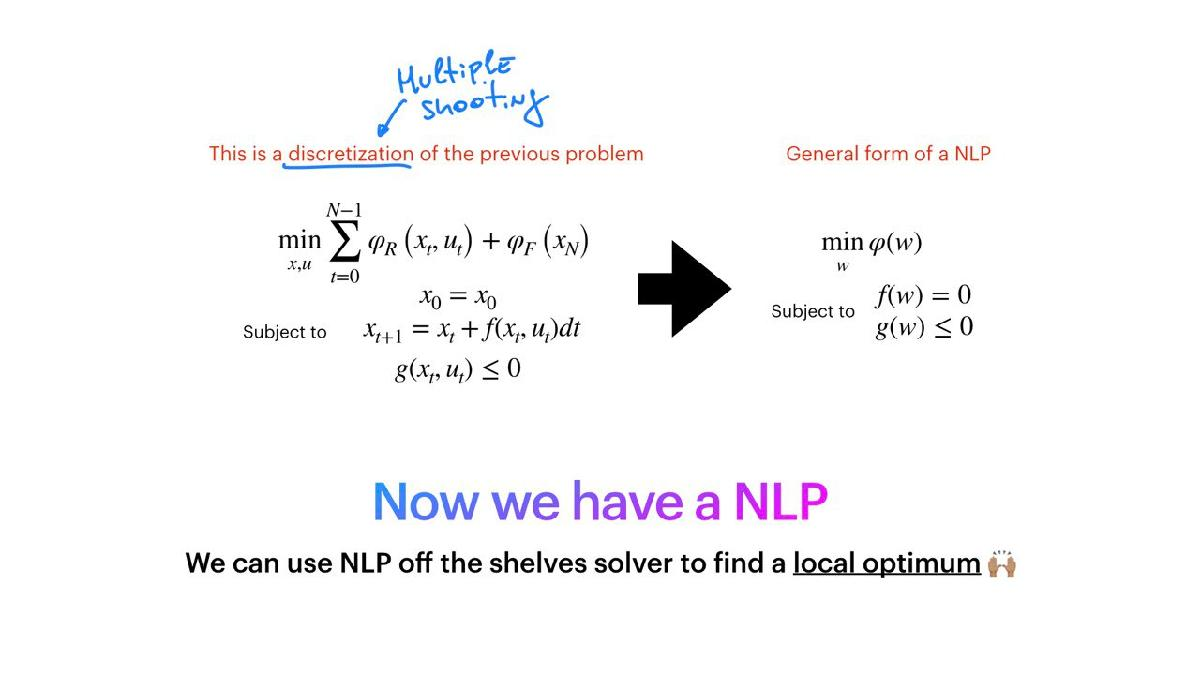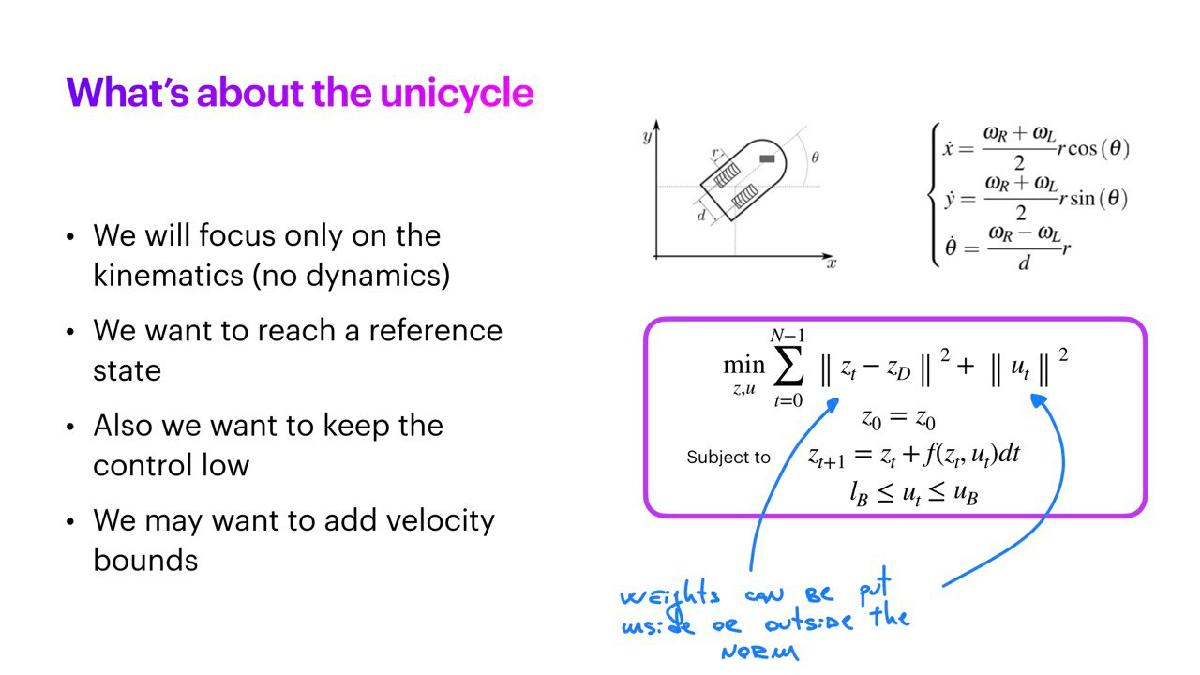OCP solution

Here we solve an optimal control problem for the differential drive unicycle. We have to find the control action (velocities) that drive the system from the starting to the arrival configuration

x_des = repmat(x_target, [1, N+1]);
[x_opt, u_opt] = solve_ocp(r, d, x_start, x_des, dt, N, w_x, w_u); % Check the function for details


Here we integrate the control action. Why this is needed? 

This function is kind of a "simulator". First of all usually when solving an OCP the timestep is quite large with respect to the one of a simulator. This function allows you to set a dt of the simulator smaller in order to have more accurate results. You may also want to use a different integration scheme and compare the results with the one you are using inside the ocp formulation.

The main point in this example though, is to show where the robot would be when it gets kicked. In the ocp formulation there is no kick, and the prediction of the state will be wrong in presence of disturbances.

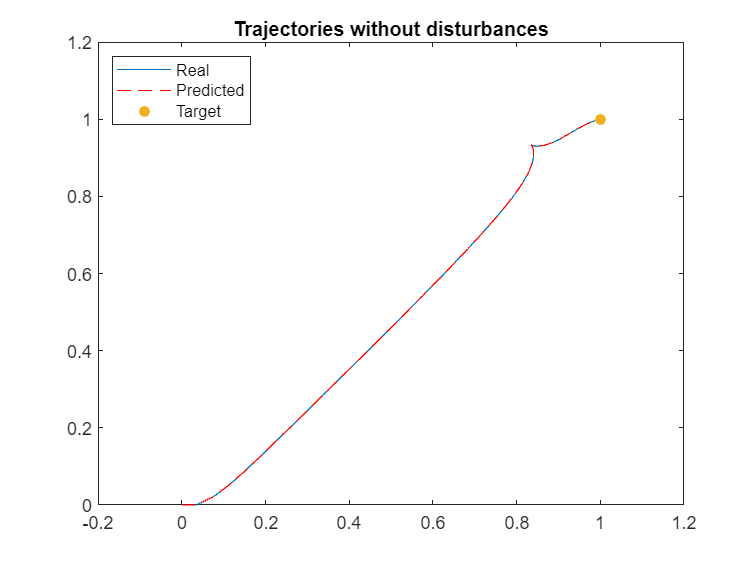

x_int = integrate_unicycle(r, d, x_start, u_opt, dt, N, 0); 

% Plot the optimal trajectory
plot(x_int(1,:), x_int(2, :))
hold on
plot(x_opt(1, :), x_opt(2, :), ['--', 'r'])
hold on
scatter(x_target(1), x_target(2), 'filled')
hold off
lgd = legend("Real", "Predicted", "Target"); 
lgd.Location = 'northwest';
title("Trajectories without disturbances")

Let's see an animation of the system

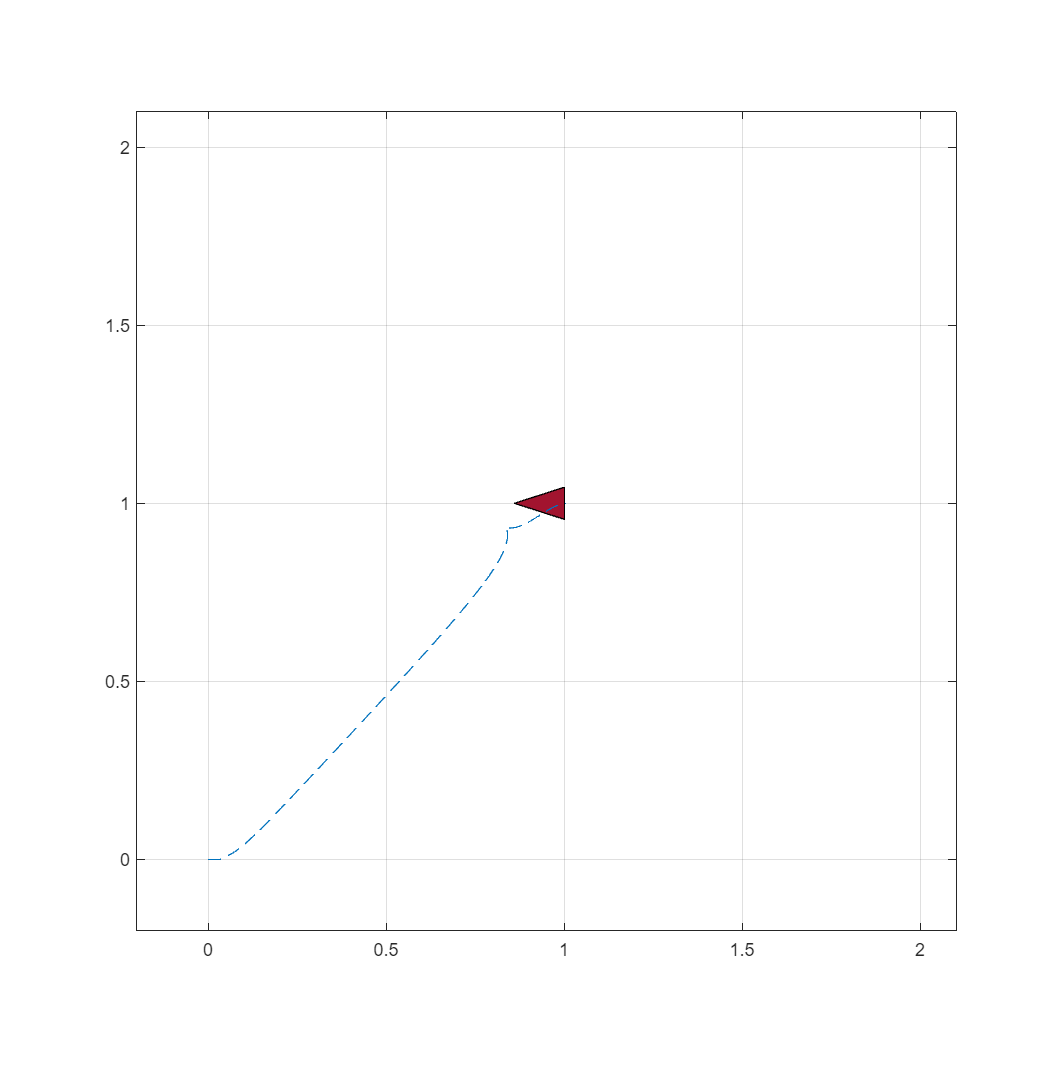

draw_unicycle(x_opt, x_des, rob_diam)
hold off

Open the animation [Here](https://www.youtube.com/watch?v=D5n3s48f4d8)

Now show the control actions

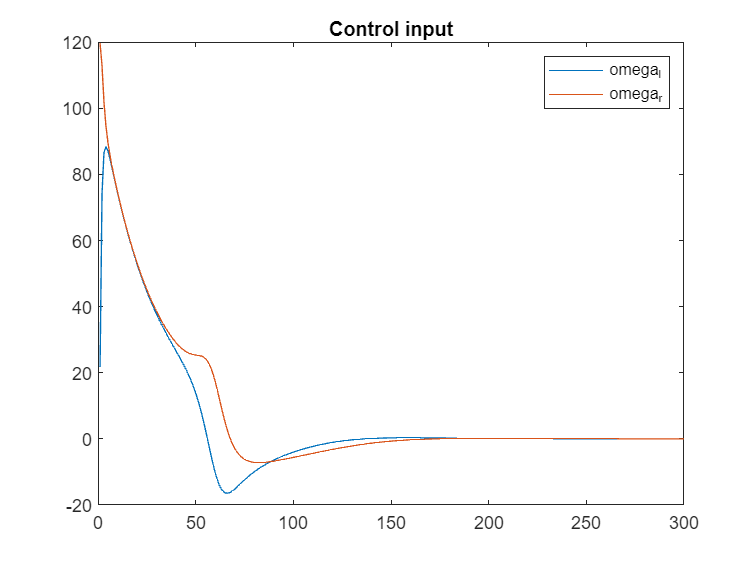

figure(3)
plot(u_opt(1, :))
hold on
plot(u_opt(2, :))
hold off
title("Control input")
legend("omega_l", "omega_r")

### 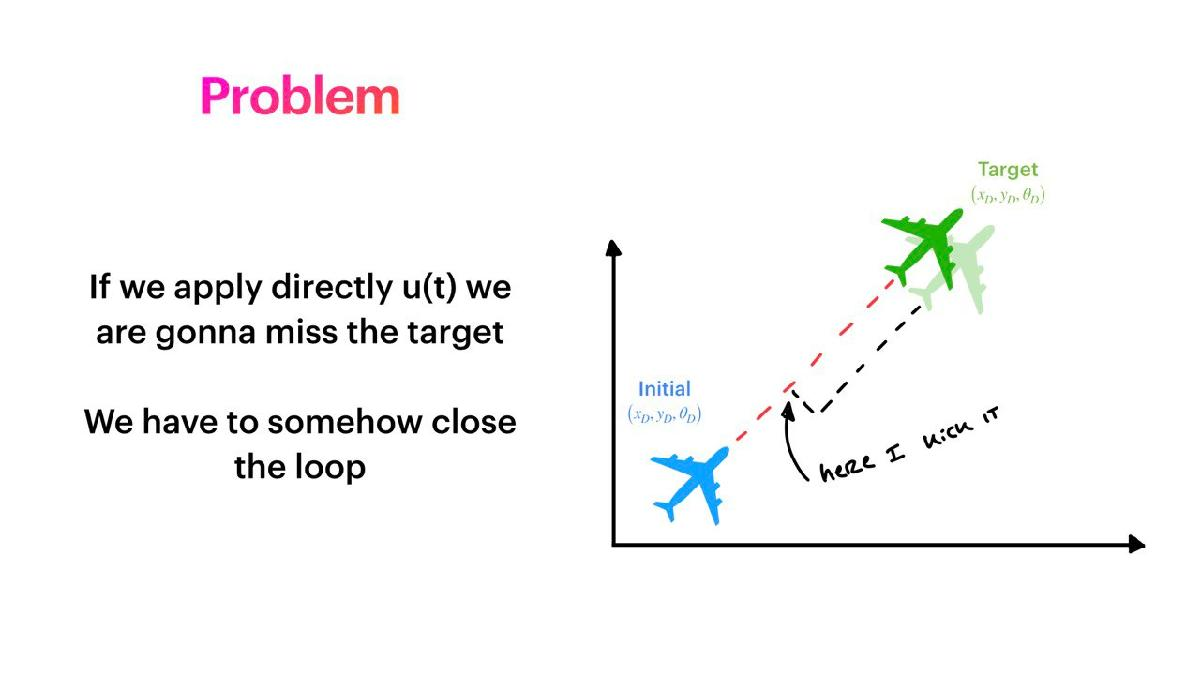Problem of Open loop trajectory tracking

With the last parameter set as 1 we are "kicking" the robot at a certain instant so we can see how the robot behaves

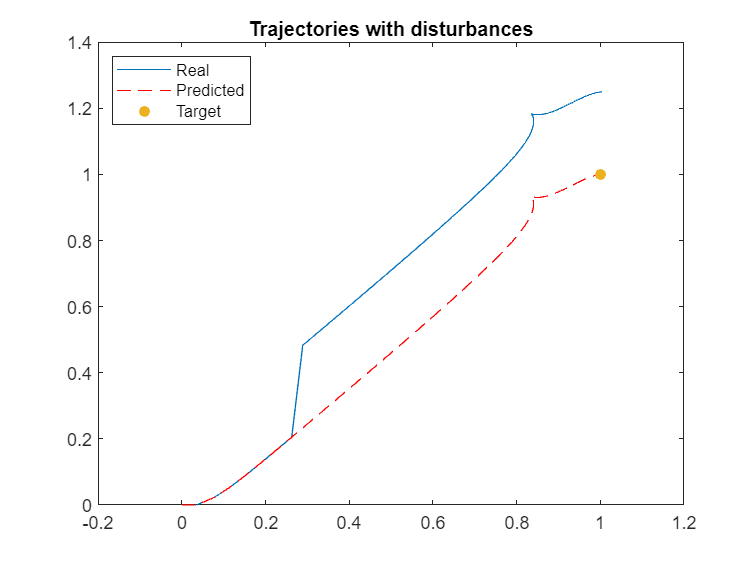

x_int = integrate_unicycle(r, d, x_start, u_opt, dt, N, Nk);
figure(4)
plot(x_int(1,:), x_int(2, :))
hold on
plot(x_opt(1, :), x_opt(2, :), '--r')
hold on
scatter(x_target(1), x_target(2), 'filled')
hold off
title("Trajectories with disturbances")
lgd = legend("Real", "Predicted", "Target"); 
lgd.Location = 'northwest';

### 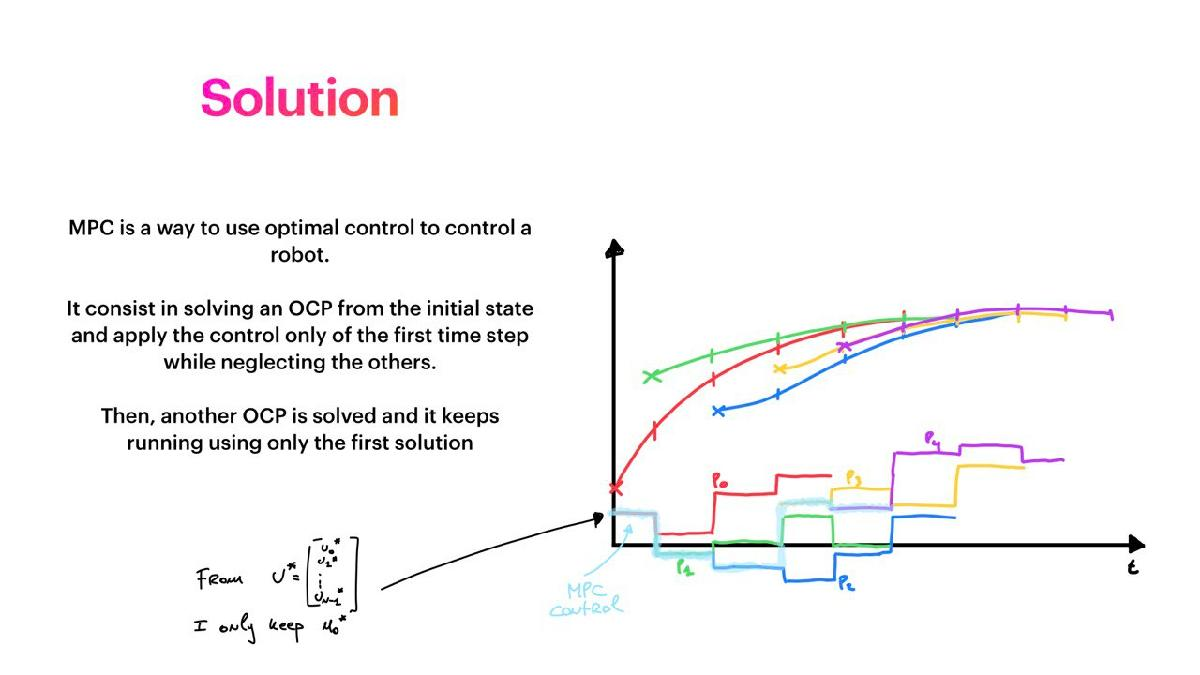MPC

This run really slow. It can be improved A LOT, but for didactic purposes it's easier to understand

T_mpc = 3; % For how long we want to control the robot (in seconds)
N_mpc = round(T_mpc/dt,0);

x_mpc = zeros(3, N_mpc);
u_mpc = zeros(2, N_mpc);

for i=1:N_mpc
    disp(strcat("Solving... iteration: ", int2str(i), " / ", int2str(N_mpc)))
    if i == 1
        x0 = x_start;
    else
        % In a real case here we wold put a sensor reading
        x0 = x_mpc(:, i-1);
        if i == Nk % Here we kick the robot
            x0 = x0 + [0; 0.25; 0]; % this is the displacement that it gets
        end
    end
    
    % Basically we are iteratively solving OCPs with different initial
    % conditions
    [x_s, u_s] = solve_ocp(r,d, x0, x_des, dt, N, w_x, w_u);
    x_mpc(:, i) = x_s(:, 2);
    u_mpc(:, i) = u_s(:, 1);
end

Solving... iteration: 1 / 300
Solving... iteration: 2 / 300
Solving... iteration: 3 / 300
Solving... iteration: 4 / 300
Solving... iteration: 5 / 300
Solving... iteration: 6 / 300
Solving... iteration: 7 / 300
Solving... iteration: 8 / 300
Solving... iteration: 9 / 300
Solving... iteration: 10 / 300
Solving... iteration: 11 / 300
Solving... iteration: 12 / 300
Solving... iteration: 13 / 300
Solving... iteration: 14 / 300
Solving... iteration: 15 / 300
Solving... iteration: 16 / 300
Solving... iteration: 17 / 300
Solving... iteration: 18 / 300
Solving... iteration: 19 / 300
Solving... iteration: 20 / 300
Solving... iteration: 21 / 300
Solving... iteration: 22 / 300
Solving... iteration: 23 / 300
Solving... iteration: 24 / 300
Solving... iteration: 25 / 300
Solving... iteration: 26 / 300
Solving... iteration: 27 / 300
Solving... iteration: 28 / 300
Solving... iteration: 29 / 300
Solving... iteration: 30 / 300
Solving... iteration: 31 / 300
Solving... iteration: 32 / 300
Solving... iterat

Now you can see that the kick is compensated

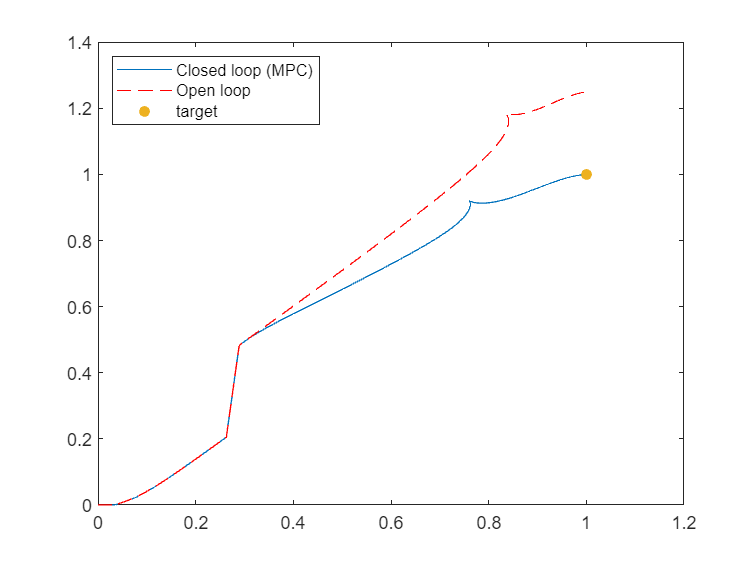

x_int_mpc = integrate_unicycle(r, d, x_start, u_mpc, dt, N_mpc, Nk);
figure()
plot(x_int_mpc(1,:), x_int_mpc(2, :))
hold on
plot(x_int(1, :), x_int(2, :), '--r')
hold on 
scatter(x_target(1), x_target(2), 'filled')
hold off
lgd = legend("Closed loop (MPC)", "Open loop", "target");
lgd.Location='northwest';

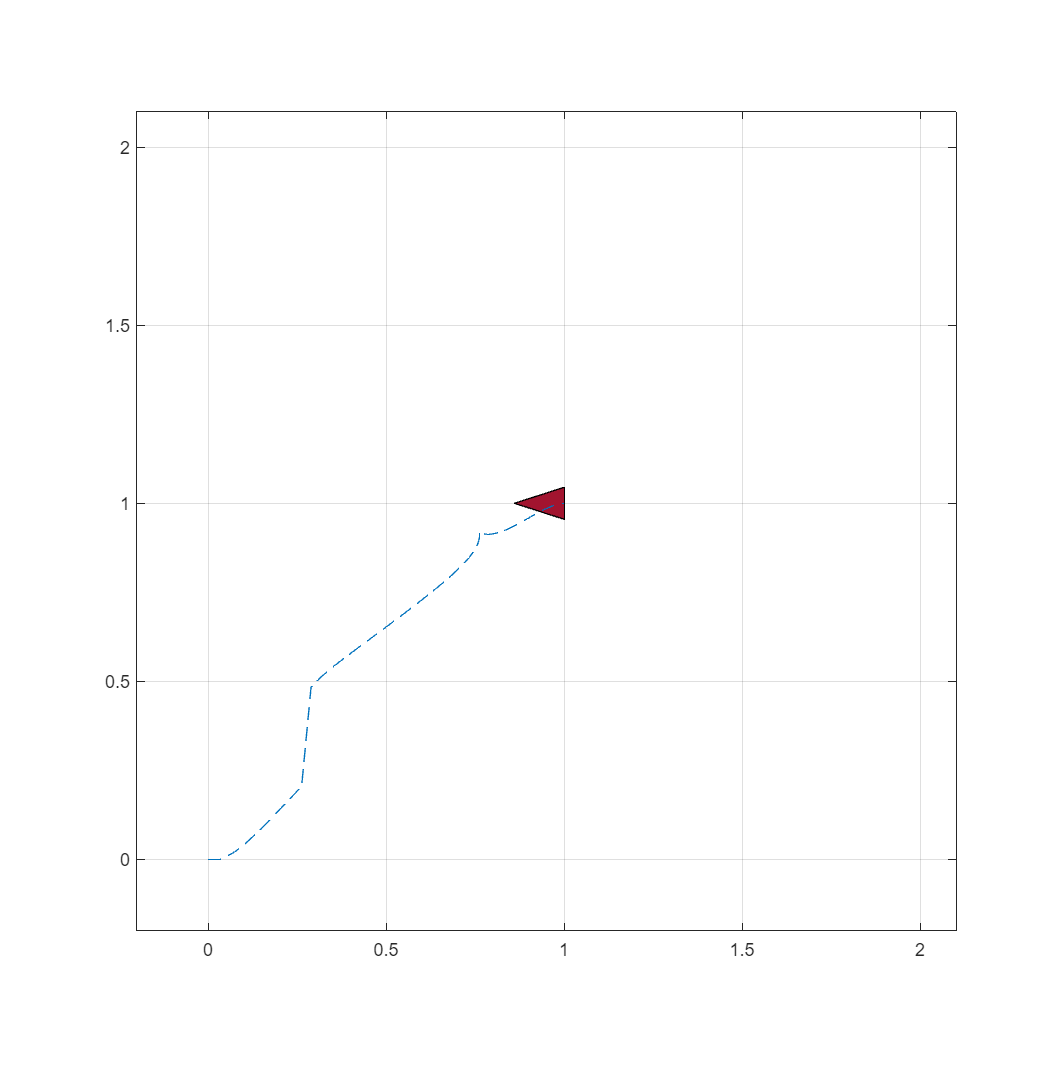

% Display the movement
draw_unicycle(x_int_mpc, x_des, rob_diam)
hold off

Open the animation [Here](https://www.youtube.com/watch?v=RoY64kNS10c)

### Trajectory following

 It is really the same as before, but in this case the reference is moving

% Define a Circle
a = 1; b=1; radius_tracking = 0.5;
theta0 = 0;
dtheta_des = 2; % Desired angular velocity

circle_des = circle(a, b, radius_tracking, theta0, dtheta_des, dt, N+1);
traj_d = circle_des;
traj_d(3, :) = circle_des(3, :) + pi/2;% sum 90 deg to have the tangent to the point

w_x = [1e2; 1e2; 1e1];
w_u = [3*1e-1; 3*1e-1];
x0 = [1; 1; 0];

Open loop trajectory tracking

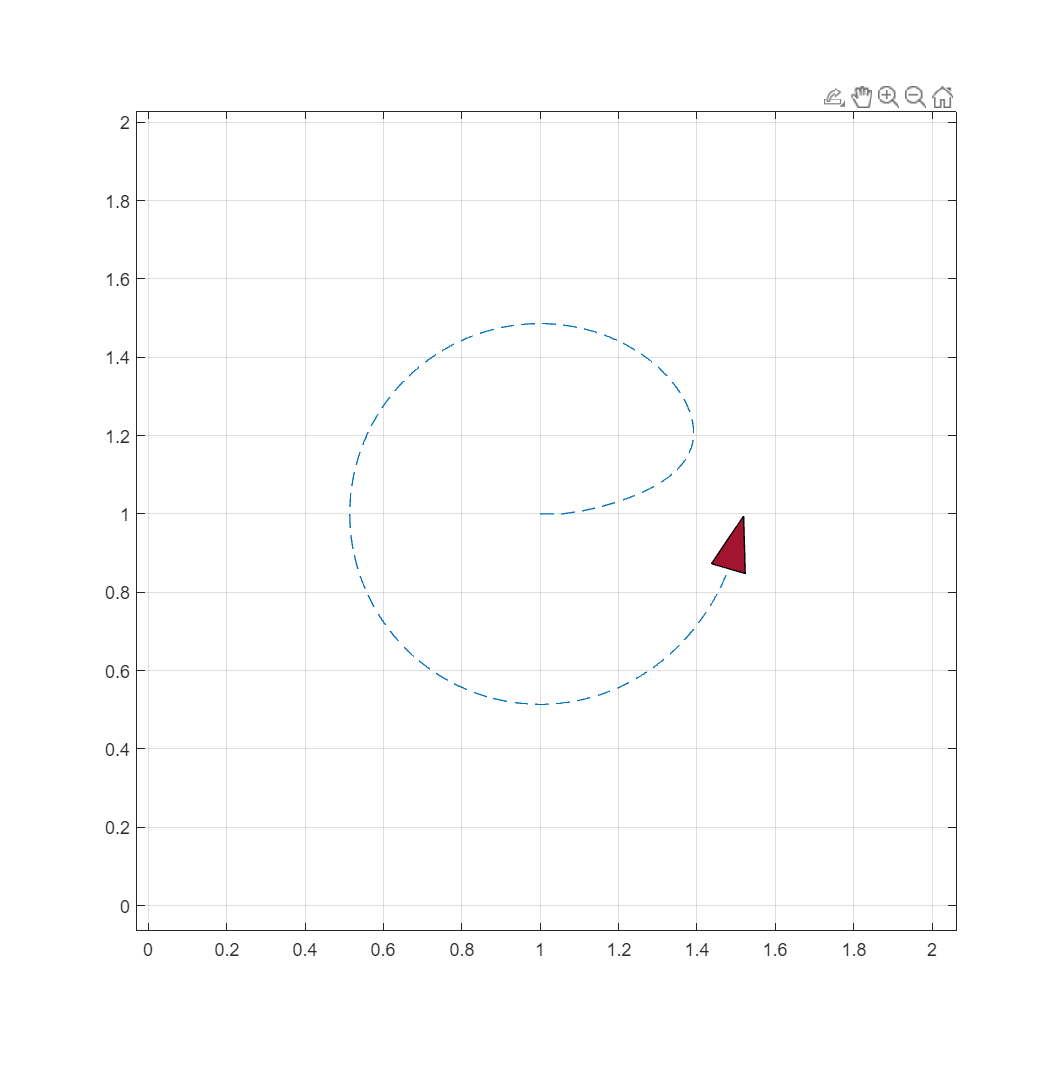

[x_s, u_s] = solve_ocp(r, d, x0, traj_d, dt, N, w_x, w_u);
draw_unicycle(x_s, traj_d, rob_diam)
hold off

Open the animation [Here](https://www.youtube.com/watch?v=RqIaF9cKVXs)

This has the same problem seen before. So let's close the loop with MPC

for i=1:N_mpc
    disp(strcat("Solving... iteration: ", int2str(i), " / ", int2str(N_mpc)))
    if i == 1
        x0 = x0;
    else
        % In a real case here we wold put a sensor reading
        x0 = x_mpc(:, i-1);
    end

    circle_des = circle(a, b, radius_tracking, circle_des(3, 2), dtheta_des, dt, N); % receding horizon
    traj_d = circle_des;
    traj_d(3, :) = circle_des(3, :) + pi/2; % sum 90 deg to have the tangent to the point
    [x_s, u_s] = solve_ocp(r, d, x0, traj_d, dt, N, w_x, w_u);
    x_mpc(:, i) = x_s(:, 2);
    u_mpc(:, i) = u_s(:, 1);

end

Solving... iteration: 1 / 300
Solving... iteration: 2 / 300
Solving... iteration: 3 / 300
Solving... iteration: 4 / 300
Solving... iteration: 5 / 300
Solving... iteration: 6 / 300
Solving... iteration: 7 / 300
Solving... iteration: 8 / 300
Solving... iteration: 9 / 300
Solving... iteration: 10 / 300
Solving... iteration: 11 / 300
Solving... iteration: 12 / 300
Solving... iteration: 13 / 300
Solving... iteration: 14 / 300
Solving... iteration: 15 / 300
Solving... iteration: 16 / 300
Solving... iteration: 17 / 300
Solving... iteration: 18 / 300
Solving... iteration: 19 / 300
Solving... iteration: 20 / 300
Solving... iteration: 21 / 300
Solving... iteration: 22 / 300
Solving... iteration: 23 / 300
Solving... iteration: 24 / 300
Solving... iteration: 25 / 300
Solving... iteration: 26 / 300
Solving... iteration: 27 / 300
Solving... iteration: 28 / 300
Solving... iteration: 29 / 300
Solving... iteration: 30 / 300
Solving... iteration: 31 / 300
Solving... iteration: 32 / 300
Solving... iterat

Finally check the solution

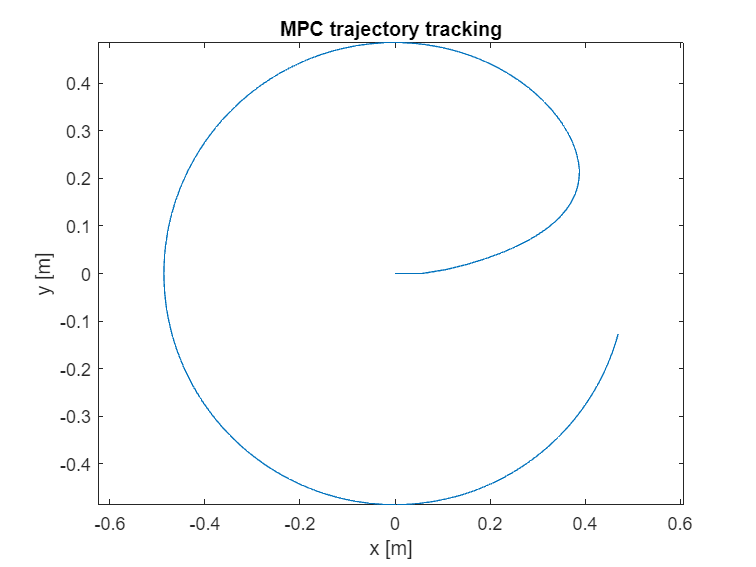

x_int_mpc = integrate_unicycle(r, d, x_start, u_mpc, dt, N_mpc, 0);
figure()
plot(x_int_mpc(1,:), x_int_mpc(2, :))
axis equal
title("MPC trajectory tracking")
xlabel("x [m]")
ylabel('y [m]')
hold off